#### Laser Power Calibration - May 24 2024

% Housekeeping

close all;
clc;
clear;
format long;

data_path = "/Users/haydnflemming/Desktop/LLAMPE - Research Project/Data/";
file_name = "Automated_Laser_Power_Calibration.xlsx";
file_path = strcat(data_path,file_name);
data1 = readmatrix(file_path);

current = data1(:,2);
current_err = data1(:,3);
objective = data1(:,4);
objective_err = data1(:,5);

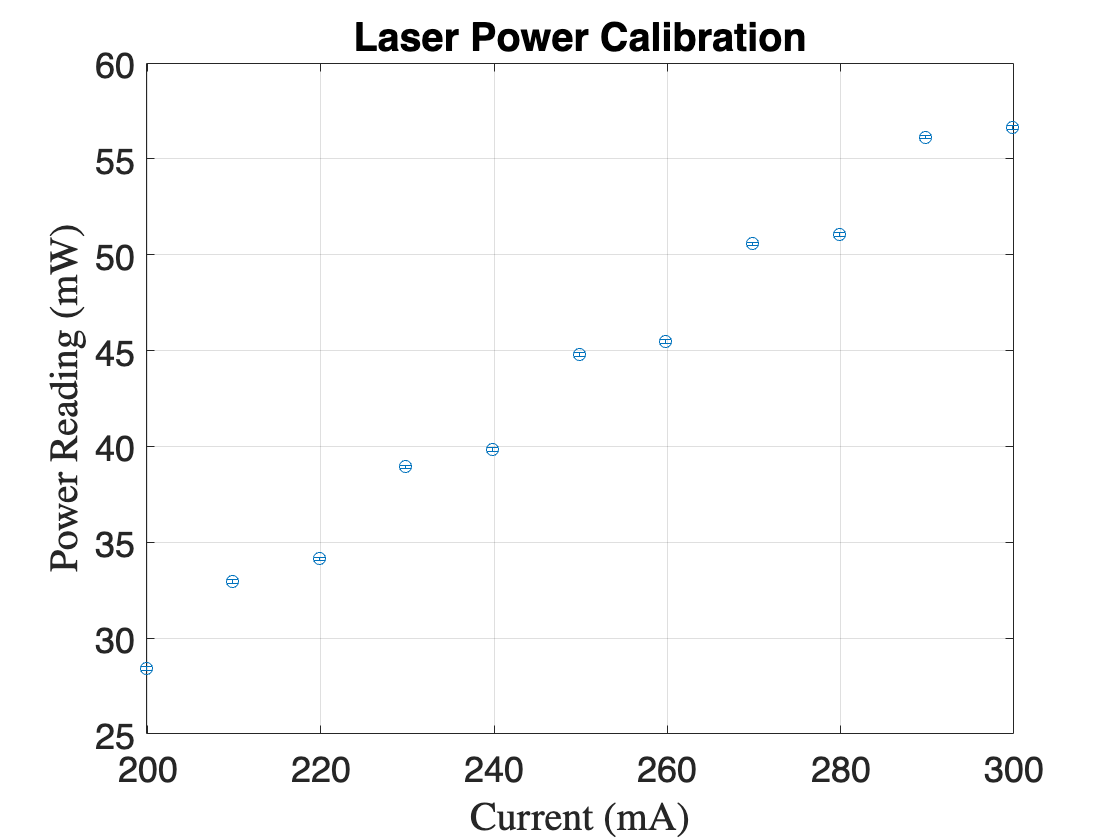

% Plotting initial calibration data

fig1 = figure;
ax1 = axes(fig1);
hold on
grid on

errorbar(ax1, current, objective, objective_err, objective_err, "o");
ax1.FontSize = 12;
ax1.Box = "on";
xlabel(ax1, "Current (mA)", 'Interpreter', 'latex');
ylabel(ax1, "Power Reading (mW)", 'Interpreter', 'latex');
title("Laser Power Calibration")
ax1.FontSize = 18;

% Fitting data with trendlines

% ft = fittype('a*x + b');
% [f, gof, fit_output] = fit(power, source, ft, 'Weights', source_err.^(-2), 'StartPoint', [1, 0])
% plot the fit function with its estimated parameters 
% use a linespace to get your x-values 

% x = linspace(0, 500, 1000);
% y = f.a*x + f.b;
% plot(ax1, x, y,'b-', 'LineWidth', 1.5);
% ax1.XLim = [0 500];
% 
% [f1, gof1, fit_output1] = fit(power, objective, ft, 'Weights', objective_err.^(-2), 'StartPoint', [0.5, 0])
% plot the fit function with its estimated parameters 
% use a linespace to get your x-values 

% x1 = linspace(0, 500, 1000);
% y1 = f1.a*x + f1.b;
% plot(ax1, x1, y1,'r-', 'LineWidth', 1.5);
% ax1.XLim = [0 500];

% Performing goodness of fit calculations

% Source fit goodness

% min_chi2 = gof.sse;
% ndof = gof.dfe;
% p_value = chi2cdf(min_chi2, ndof, 'upper')
% reduced_chi2 = min_chi2/ndof
% % Objective fit goodness
% 
% min_chi2 = gof1.sse;
% ndof = gof1.dfe;
% p_value = chi2cdf(min_chi2, ndof, 'upper')
% reduced_chi2 = min_chi2/ndof